# Sinusoidal Input 

## Load 0.2Freq

load('20_02_f.mat');

Input values

y1=scope.signals(1).values; 

y1=y1.';
x1=tout;
x1=x1.';

figure
plot(x1,y1);
hold on

Response values

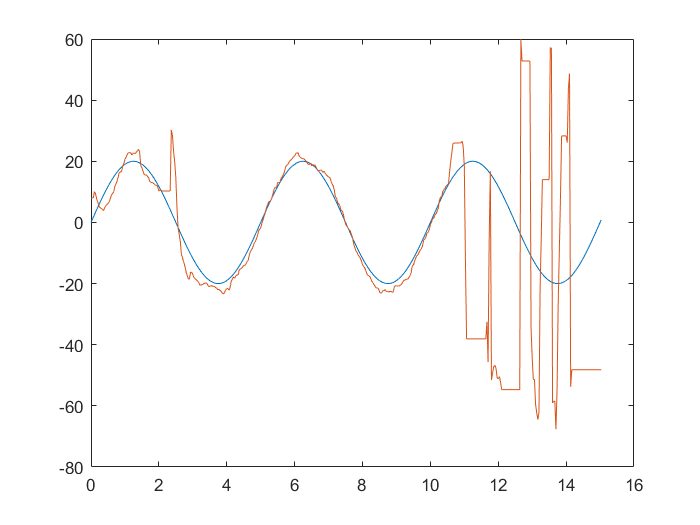

y2=scope.signals(2).values; 

y3=squeeze(y2);
y3=y3.';
constref=80;
y3=y3-constref;

plot(x1,y3);
hold off

Chosing points

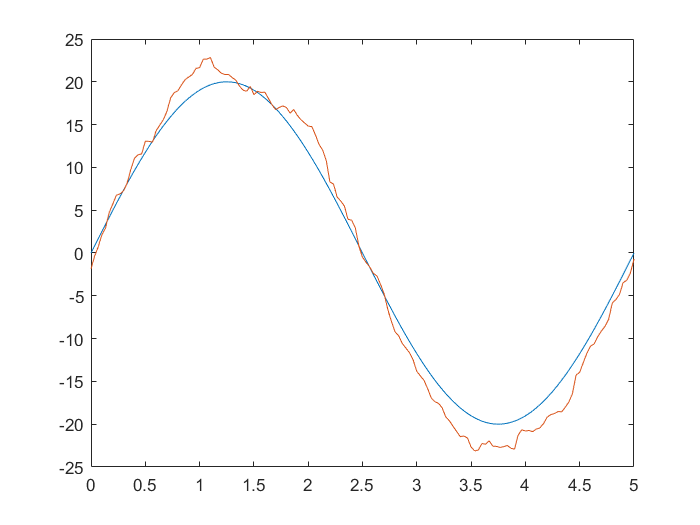

chosen_ref=y1(151:301);
chosen_t=x1(1:151);

plot(chosen_t,chosen_ref);
hold on

chosen_y=y3(151:301);

plot(chosen_t,chosen_y);
hold off

Finding data

Ts=1/30;

[gain, phase, w] = findbodedata2(chosen_ref, chosen_y, Ts, 0)

gain = 0.9961

phase = -0.5710

w =     0.7363    0.7363


Comparing data

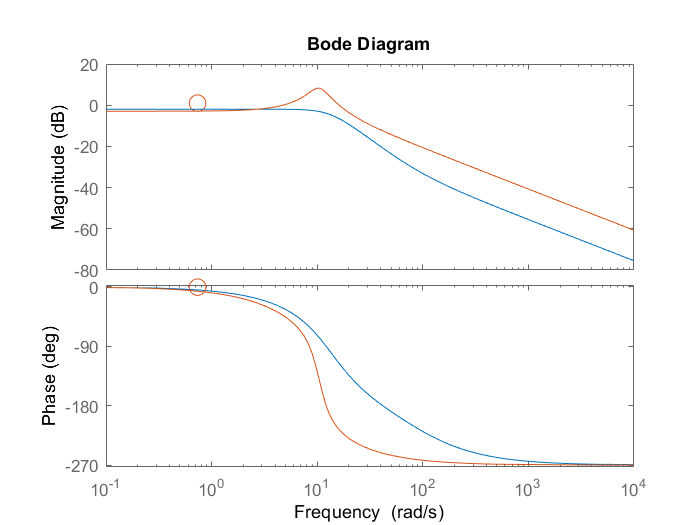

figure
semilogx(w,gain,'o','MarkerSize',10)
hold on

h=bodeplot(Gs_30_final);
opt = getoptions(h);  %phase offset correction
opt.PhaseMatching = 'on'; 
opt.PhaseMatchingFreq = 0.1; 
opt.PhaseMatchingValue = 0;
setoptions(h,opt); %update phase plot
hold on

semilogx(w,phase,'o','MarkerSize',10)
hold on

h=bodeplot(Gs_levy);
opt = getoptions(h);  %phase offset correction
opt.PhaseMatching = 'on'; 
opt.PhaseMatchingFreq = 0.1; 
opt.PhaseMatchingValue = 0;
setoptions(h,opt); %update phase plot
hold off

## Load 0.4Freq

load('20_04_f.mat');

Input values

y1=scope.signals(1).values; 

y1=y1.';
x1=tout;
x1=x1.';

figure
plot(x1,y1);
hold on

Response values

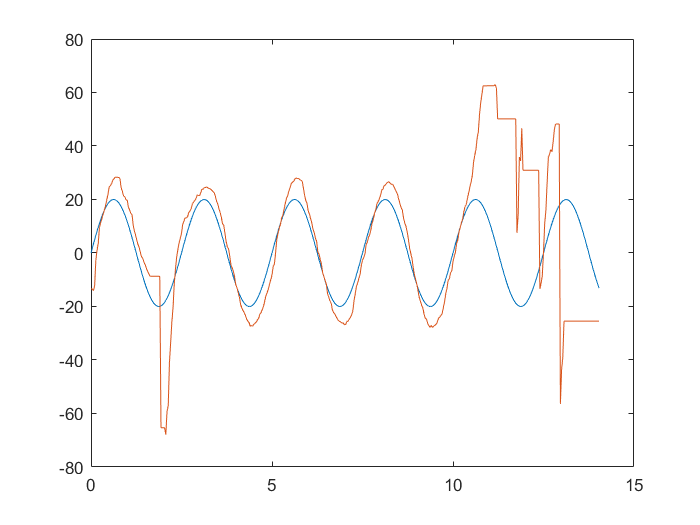

y2=scope.signals(2).values; 

y3=squeeze(y2);
y3=y3.';
constref=80;
y3=y3-constref;

plot(x1,y3);
hold off

Chosing points

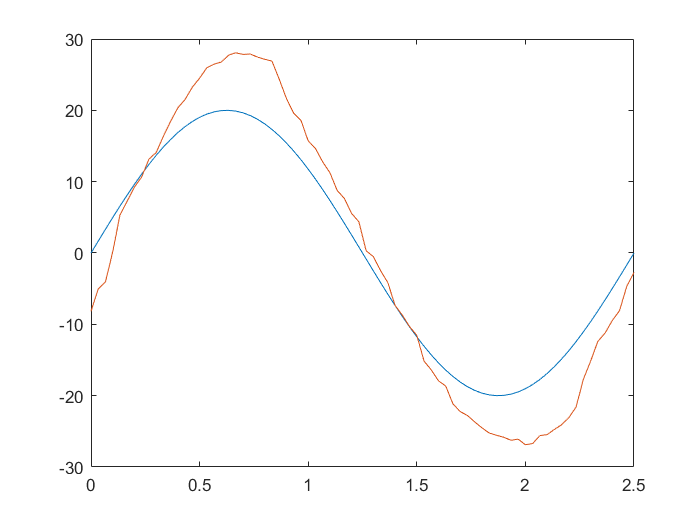

chosen_ref=y1(151:226);
chosen_t=x1(1:76);

plot(chosen_t,chosen_ref);
hold on

chosen_y=y3(151:226);

plot(chosen_t,chosen_y);
hold off

Finding data

Ts=1/30;

[gain, phase, w] = findbodedata2(chosen_ref, chosen_y, Ts, 0)

gain = 2.5484

phase = -5.2187

w =     1.4726    1.4726


Comparing data

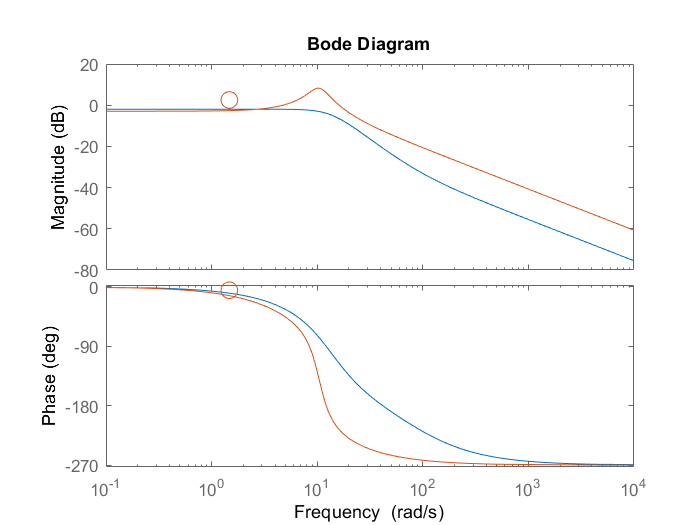

figure
semilogx(w,gain,'o','MarkerSize',10)
hold on

h=bodeplot(Gs_30_final);
opt = getoptions(h);  %phase offset correction
opt.PhaseMatching = 'on'; 
opt.PhaseMatchingFreq = 0.1; 
opt.PhaseMatchingValue = 0;
setoptions(h,opt); %update phase plot
hold on

semilogx(w,phase,'o','MarkerSize',10)
hold on

h=bodeplot(Gs_levy);
opt = getoptions(h);  %phase offset correction
opt.PhaseMatching = 'on'; 
opt.PhaseMatchingFreq = 0.1; 
opt.PhaseMatchingValue = 0;
setoptions(h,opt); %update phase plot
hold off

## Load 0.8Freq

load('20_08_f.mat');

Input values

y1=scope.signals(1).values; 

y1=y1.';
x1=tout;
x1=x1.';

figure
plot(x1,y1);
hold on

Response values

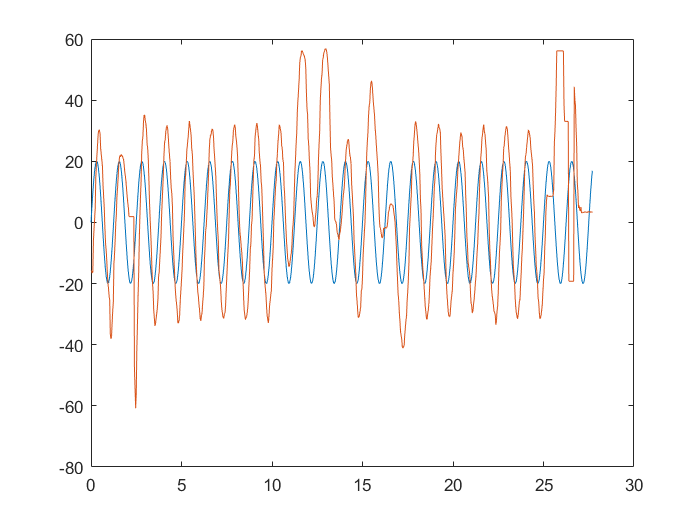

y2=scope.signals(2).values; 

y3=squeeze(y2);
y3=y3.';
constref=80;
y3=y3-constref;

plot(x1,y3);
hold off

Chosing points

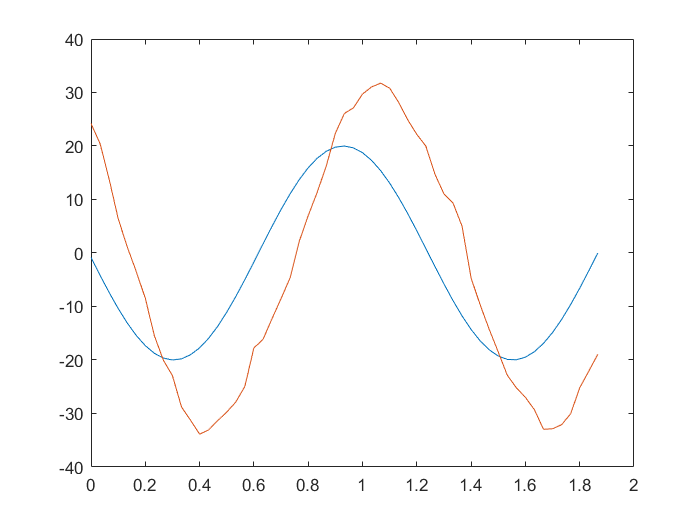

chosen_ref=y1(95:151);
chosen_t=x1(1:57);

plot(chosen_t,chosen_ref);
hold on

chosen_y=y3(95:151);

plot(chosen_t,chosen_y);
hold off

Finding data

Ts=1/30;

[gain, phase, w] = findbodedata2(chosen_ref, chosen_y, Ts, 0)

gain = 4.2314

phase = -46.0971

w =     5.8905    5.8905


Comparing data

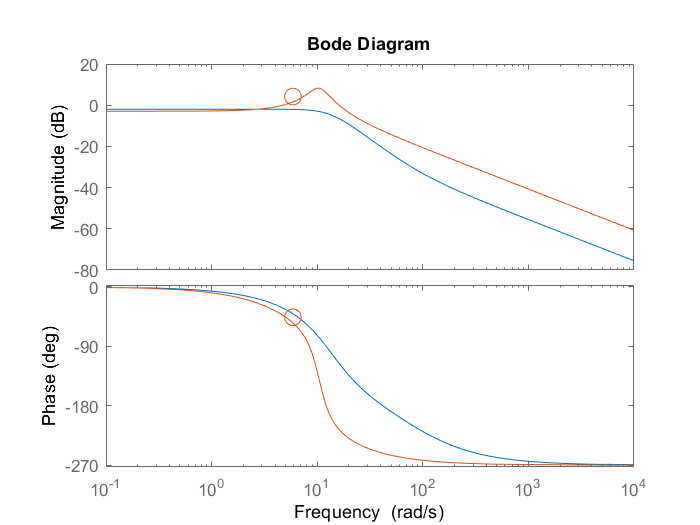

figure
semilogx(w,gain,'o','MarkerSize',10)
hold on

h=bodeplot(Gs_30_final);
opt = getoptions(h);  %phase offset correction
opt.PhaseMatching = 'on'; 
opt.PhaseMatchingFreq = 0.1; 
opt.PhaseMatchingValue = 0;
setoptions(h,opt); %update phase plot
hold on

semilogx(w,phase,'o','MarkerSize',10)
hold on

h=bodeplot(Gs_levy);
opt = getoptions(h);  %phase offset correction
opt.PhaseMatching = 'on'; 
opt.PhaseMatchingFreq = 0.1; 
opt.PhaseMatchingValue = 0;
setoptions(h,opt); %update phase plot
hold off

## Load 2.4Freq

load('20_24_f.mat');

Input values

y1=scope.signals(1).values; 

y1=y1.';
x1=tout;
x1=x1.';

figure
plot(x1,y1);
hold on

Response values

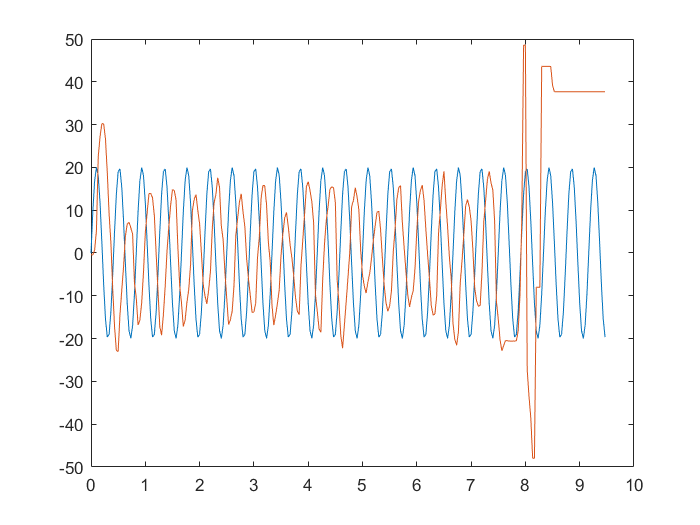

y2=scope.signals(2).values; 

y3=squeeze(y2);
y3=y3.';
constref=80;
y3=y3-constref;

plot(x1,y3);
hold off

Chosing points

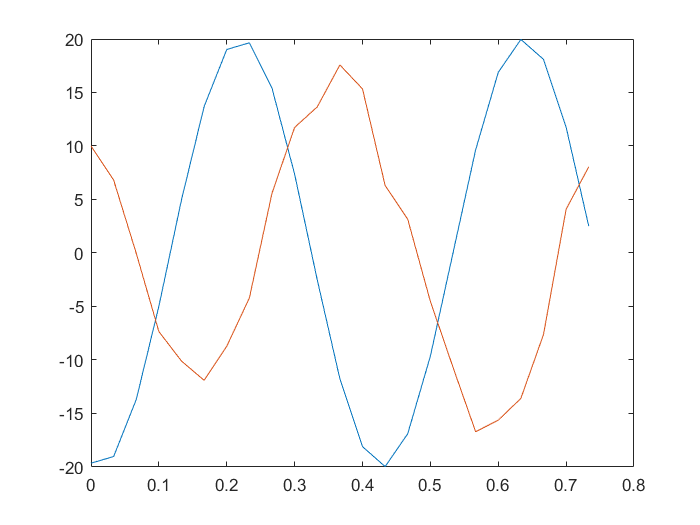

chosen_ref=y1(60:82);
chosen_t=x1(1:23);

plot(chosen_t,chosen_ref);
hold on

chosen_y=y3(60:82);

plot(chosen_t,chosen_y);
hold off

Finding data

Ts=1/30;

[gain, phase, w] = findbodedata2(chosen_ref, chosen_y, Ts, 0)

gain = -2.7888

phase = -131.5551

w =    17.6715   17.6715


% phase=-116.2283

Comparing data

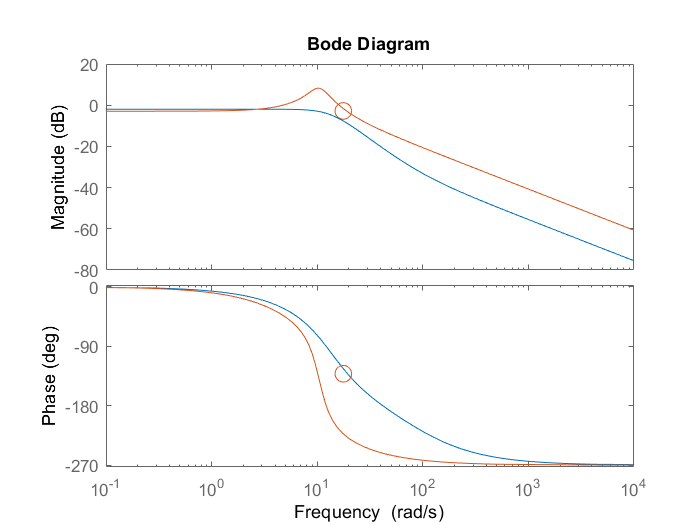

figure
semilogx(w,gain,'o','MarkerSize',10)
hold on

h=bodeplot(Gs_30_final);
opt = getoptions(h);  %phase offset correction
opt.PhaseMatching = 'on'; 
opt.PhaseMatchingFreq = 0.1; 
opt.PhaseMatchingValue = 0;
setoptions(h,opt); %update phase plot
hold on

semilogx(w,phase,'o','MarkerSize',10)
hold on

h=bodeplot(Gs_levy);
opt = getoptions(h);  %phase offset correction
opt.PhaseMatching = 'on'; 
opt.PhaseMatchingFreq = 0.1; 
opt.PhaseMatchingValue = 0;
setoptions(h,opt); %update phase plot
hold off

## Load 2.8Freq

load('20_28_f.mat');

Input values

y1=scope.signals(1).values; 

y1=y1.';
x1=tout;
x1=x1.';

figure
plot(x1,y1);
hold on

Response values

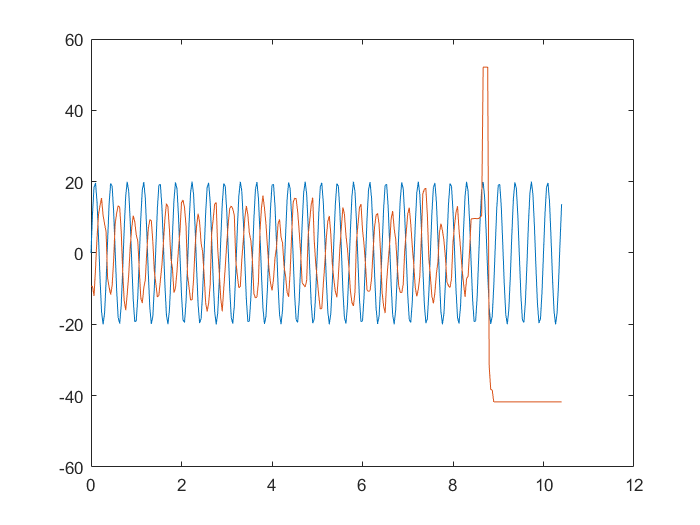

y2=scope.signals(2).values; 

y3=squeeze(y2);
y3=y3.';
constref=80;
y3=y3-constref;

plot(x1,y3);
hold off

Chosing points

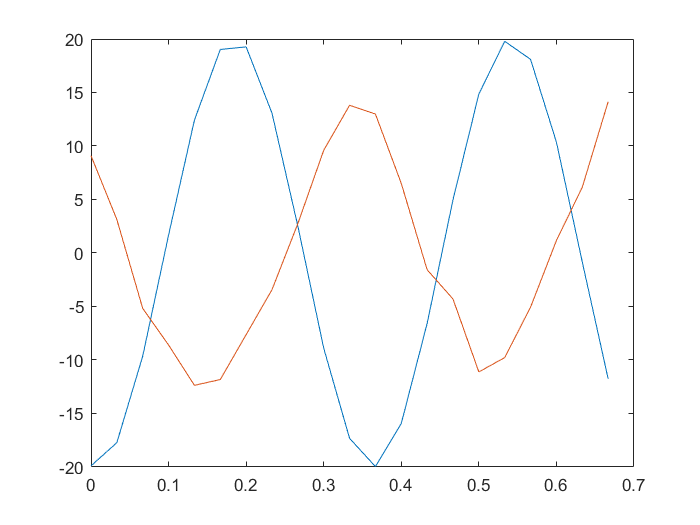

chosen_ref=y1(41:61);
chosen_t=x1(1:21);

plot(chosen_t,chosen_ref);
hold on

chosen_y=y3(41:61);

plot(chosen_t,chosen_y);
hold off

Finding data

Ts=1/30;

[gain, phase, w] = findbodedata2(chosen_ref, chosen_y, Ts, 0)

gain = -4.2465

phase = -146.6613

w =    17.6715   17.6715


Comparing data

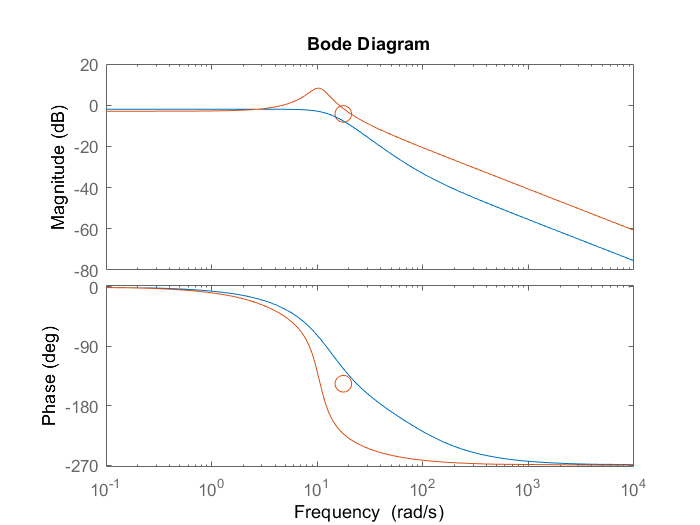

figure
semilogx(w,gain,'o','MarkerSize',10)
hold on

h=bodeplot(Gs_30_final);
opt = getoptions(h);  %phase offset correction
opt.PhaseMatching = 'on'; 
opt.PhaseMatchingFreq = 0.1; 
opt.PhaseMatchingValue = 0;
setoptions(h,opt); %update phase plot
hold on

semilogx(w,phase,'o','MarkerSize',10)
hold on

h=bodeplot(Gs_levy);
opt = getoptions(h);  %phase offset correction
opt.PhaseMatching = 'on'; 
opt.PhaseMatchingFreq = 0.1; 
opt.PhaseMatchingValue = 0;
setoptions(h,opt); %update phase plot
hold off

Concluding

gain=[0.9961 2.5484 4.2314 -2.7888 -4.2465];
phase=[-0.7100 -5.2187 -46.0971 -131.5551 -146.6613];
w=[0.7363 1.4726 5.8905 17.615 23.5619];